**Skills 8: Kinetics and dissolved oxygen dynamics in aquatic systems**

**1.)**

**Given: **

- Initial concentration = $50\;\textrm{mg}/L$

- 
$$k_0 =0\ldotp 5\;\textrm{mg}\;l^{-1} \;{\textrm{day}}^{-1}$$


- 
$$k_1 =0\ldotp 01\;{\textrm{day}}^{-1}$$


- 
$$k_2 =0\ldotp 0002\;{\textrm{day}}^{-1} \;{\textrm{mg}}^{-1} \;l$$


C = 50;
T = [0, 25, 50, 75, 100];
k0 = 0.5;
k1 = 0.01;
k2 = 0.0002;

**Required:**

1.1) Plot concentration vs time over 100 days if removal is by zero order, first order, and second order kinetics.

1.2) Calculate and plot cumulative removal (0 to 100% vs time).

**Sketch:**

**Theory:**

This problem will use the following equations:

- Zero-order: $\frac{\textrm{dC}}{\textrm{dt}}=-k_0$

- First-order: $\frac{\textrm{dC}}{\textrm{dt}}=-k_1 *A$

- Second-order: $\frac{\textrm{dC}}{\textrm{dt}}=-k_2 *A^2$

- Percent removal: $\left(\frac{C_0 -C}{C_0 }\right)*100$

**Assumptions:**

- No additional inputs of material over time.

**Solution:**

1.1)

- Zero-order kinetics:

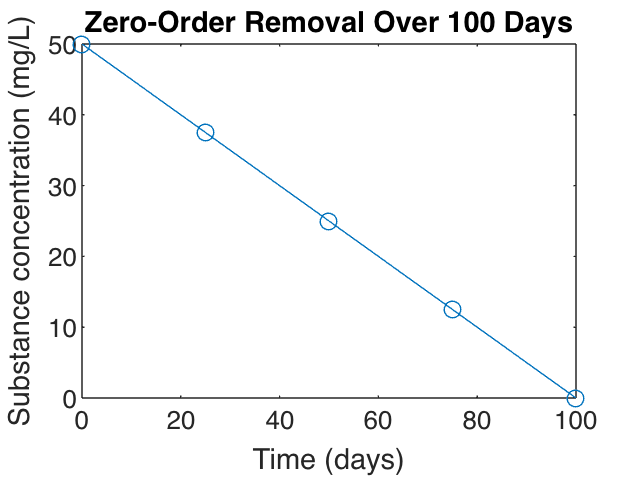

C0 = C-(k0*T);

figure
plot(T,C0,'o-')
title(["Zero-Order Removal Over 100 Days"])
ylabel("Substance concentration (mg/L)")
xlabel("Time (days)")

- First-order kinetics:

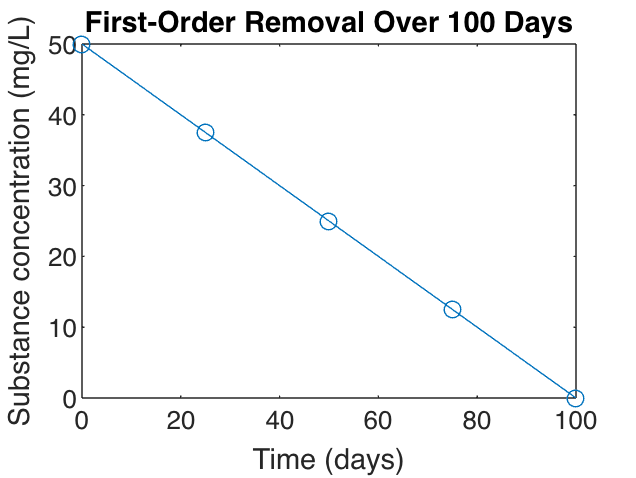

C1 = C-(k1*C*T);

figure
plot(T,C1,'o-')
title(["First-Order Removal Over 100 Days"])
ylabel("Substance concentration (mg/L)")
xlabel("Time (days)")

- Second-order kinetics:

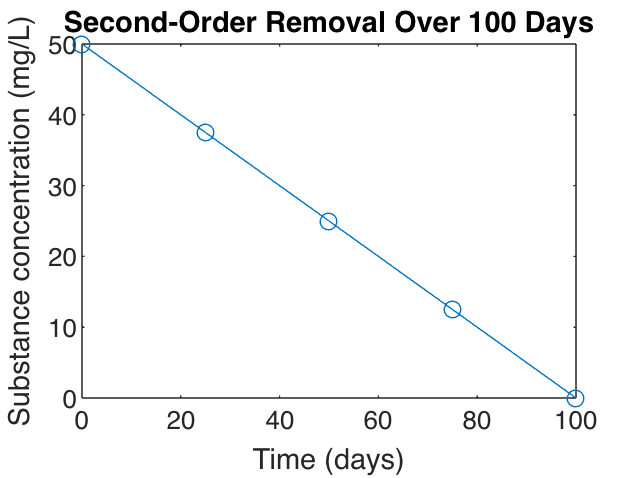

C2 = C+(-k2*(C^2)*T);

figure
plot(T,C2,'o-')
title(["Second-Order Removal Over 100 Days"])
ylabel("Substance concentration (mg/L)")
xlabel("Time (days)")

- Percent removal over time:

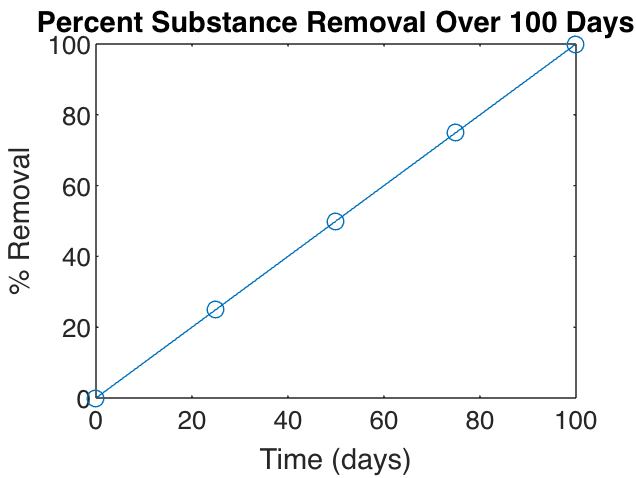

Pct = ((C-C0)/C)*100;

figure
plot(T,Pct,'o-')
title(["Percent Substance Removal Over 100 Days"])
ylabel("% Removal")
xlabel("Time (days)")

**Discussion:**

- In this case, removal of the substance using zero, first, and second order kinetics was identical. This shows the influence of the rate constant (k), which was quite different for each of the three questions. If the k values had been slightly different, then the substance removal rates would change as well.

**15.)**

**Given:**

- Elevation change = 2600 m - 700 m = 1900 m

- Average temperature = $13\degree C$ 

- 
$$\Delta X=60\;\textrm{km}$$


- Final temperature = $28\degree C$

**Required:**

Calculate and plot variation in dissolved oxygen (DO) saturation (mg/L) as a function of distance.

**Sketch:**

**Theory:**

- I will calculate $C_S$ over the distance of 10 km using the following equation (APHA, 1985):


$$C_{\textrm{SP}} =C_{\textrm{S0}} P\left\lbrack \frac{\left(1-\left(P_{\textrm{WV}} /P\right)\right)*\left(1-\theta P\right)}{\left(1-P_{\textrm{WV}} \right)*\left(1-\theta \right)}\right\rbrack$$
 

- P is calculated with the following equation (Trewartha, 1954):

$P=P_0 -\left(0\ldotp 02667\right)\left(\Delta H\right)/760$, H is in ft

- $P_{\textrm{WV}}$ is calculated from: $P_{\textrm{WV}} =216961/T^2$, T is in Kelvin (t + 273.150).

- $\theta =0\ldotp 000975-\left(1\ldotp 426*{10}^{-5} t\right)+\left(6\ldotp 436*{10}^{-8} t^2 \right),t$ is in Celsius

- 
$$\begin{array}{l}
\ln C_{\textrm{S0}} =-139\ldotp 34411+\frac{1\ldotp 575701*{10}^5 }{T}-\frac{6\ldotp 642308*{10}^7 }{T^2 }\\
+\frac{1\ldotp 243800*{10}^{10} }{T^3 }-\frac{8\ldotp 8621949*{10}^{11} }{T^4 }
\end{array}$$


- $P=P_0 *e^{\frac{-\mathrm{mgh}}{R*T_0 }}$, m is the mass of one air molecule (28.96 g/mol), g is acceleration due to gravity (9.8 m/s^2), h is height in m, R is the ideal gas constant (8.314 J/mol*K), and T0 is standard temperature at sea level (288.16 K).

**Assumptions:**

- Temperature increases proportionally with distance.

- Temperature increase of 15C per 10 km (1.5C per km).

- Decrease in altitude of 190 m per km. 

- P0 = 1 atm

**Solution:**

- I first input the needed given information (temperature, distance, altitude).

t = [13, 14.5, 16, 17.5, 19, 20.5, 22, 23.5, 25, 26.5, 28]; %temp in Celsius
T = t+273.15; %temp in Kelvin
d = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10]; %distance in km
for h = 2600:-190:700
    disp(h)
end

        2600

        2410

        2220

        2030

        1840

        1650

        1460

        1270

        1080

   890

   700



h = [2600, 2410, 2220, 2030, 1840, 1650, 1460, 1270, 1080, 890, 700]; %altitude in m

- I then calculated the variables for the final equation ($\theta ,P,P_{\textrm{WV}} ,C_{\textrm{S0}}$)

theta = 0.000975-(1.426e-5*t)+(6.546e-8*t.^2) %theta

theta = 1.0e-03 *

    0.8007    0.7820    0.7636    0.7455    0.7277    0.7102    0.6930    0.6760    0.6594    0.6431    0.6270


PWV = 216961./(t.^2) %partial pressure at sea level (atm)

PWV = 1.0e+03 *

    1.2838    1.0319    0.8475    0.7084    0.6010    0.5163    0.4483    0.3929    0.3471    0.3090    0.2767


x = -0.02896968*9.80665*h; %input for P
y = 8.314462618*288.16; %input for P
P = exp(x./y) %P in atm

P =     0.7347    0.7514    0.7686    0.7861    0.8040    0.8223    0.8410    0.8602    0.8798    0.8998    0.9203


Cso = -139.34411+(1.575701e5./T)-(6.642308e7./T.^2)+(1.243800e10./T.^3)-(8.621949e11./T.^4) %mg/L at sea level

Cso =     2.3549    2.3218    2.2895    2.2581    2.2275    2.1976    2.1683    2.1398    2.1118    2.0845    2.0577


- Final solution solving for Csp:

Csp = Cso.*P*((1-(PWV./P).*(1-theta.*P))/((1-PWV).*(1-theta)))

Csp =     2.2437    2.2625    2.2820    2.3019    2.3224    2.3434    2.3650    2.3870    2.4095    2.4325    2.4559


- Plotted DO concentration ($C_{\mathrm{SP}}$) vs distance:

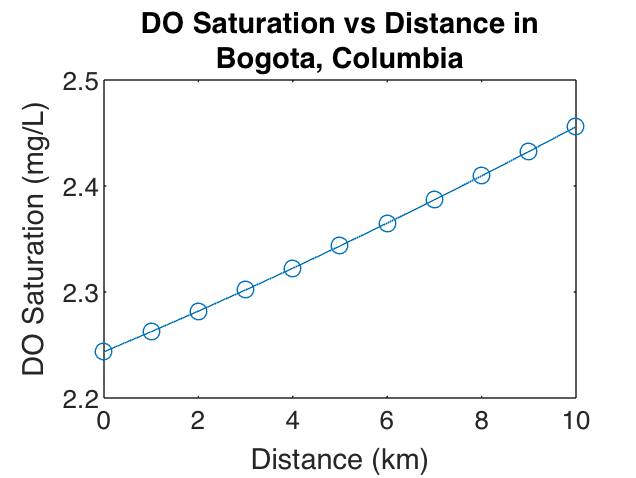

figure
plot(d,Csp,'o-')
title(["DO Saturation vs Distance in", "Bogota, Columbia"])
ylabel("DO Saturation (mg/L)")
xlabel("Distance (km)")

**Discussion:**

- Dissolved oxygen increases over distance, which makes sense in this case because the atlitude is decreasing with increasing distance. This means that the amount of oxygen should increase.

**16.)**

**Given:**

- Initial DO reading = $1\;\textrm{mg}/L$

- Temperature = $20\degree C$

- Rearation rate = $0\ldotp 8/\textrm{day}$

- Second DO reading = $5\ldotp 6\;\textrm{mg}/L$

- Third DO reading = $3\ldotp 6\;\textrm{mg}/L$

C1 = 1;
C2 = 5.6;
C3 = 3.6;
C4 = 7;
k = 0.8; %reaeration rate

**Required:**

Calculate how long it will take for the DO to reach $7\;\textrm{mg}/L$ starting from the initial DO reading of $1\;\textrm{mg}/L$.

**Sketch:**

**Theory:**

This problem will be solved using the first-order kinetics equation rearranged to solve for time (days) for both the first and second rearation.


$$C=C_0 +\left(k*C_0 *T\right)\longrightarrow T=\frac{C-C_0 }{k*C_0 }$$


**Assumptions:**

- Assuming first-order kinetics because of the units of the reaeration rate (${\textrm{time}}^{-1}$).

**Solution:**

- First aeration:

T1 = (C2-C1)/(k*C1) %time in days

T1 = 5.7500

- Second aeration:

T2 = (C4-C3)/(k*C3) %time in days

T2 = 1.1806

- Final time required = $T_1 +T_2 =5\ldotp 75\;\textrm{days}+1\ldotp 18\;\textrm{days}=6\ldotp 93\;\textrm{days}$

**Discussion:**

- It will take just under seven days for the dissolved oxygen concentration to reach $7\;\textrm{mg}/L$ using the given parameters.

**17.)**

**Given:**

- Reaeration rate at $30\degree C$ = $0\ldotp 5/\textrm{day}$

**Required:**

- Plot the DO concentration profile in mg/L from $t^* =0$ to $t^* =5$ days.

**Sketch:**

**Theory:**

- I will use first-order kinetics to solve this problem with following equation:


$$C=C_0 +\left(k*C_0 *T\right)$$


- I will also calculate the rearation rate (k) at $t^* =0$ ($20\degree C$) using the following equation and assuming that the process dependent constant ($\theta$) = 1.075:


$$k\left(20\right)=k\left(30\right)*\theta^{20-30}$$


k30 = 0.5; %1/day
k20 = k30*(1.075^(20-30)) %1/day

k20 = 0.2426

**Assumptions:**

- Assume first-order kinetics

- Assume temperature is $20\degree C$ at $t^* =0$, then immediately increasing to $30\degree C$.

- Assume initial DO of $10\;\textrm{mg}/L$

**Solution:**

- I calculated the initial concentration at  $t^* =0$ using a rearation rate of 0.2426/day:

C0 = 10 + (k20*10)%mg/L

C0 = 12.4260

- I then calculated and plotted the rest of the DO concentration profile up to $t^* =5\;\textrm{days}$ using k = 0.5/days and a starting DO concentration of 12.43 mg/L:

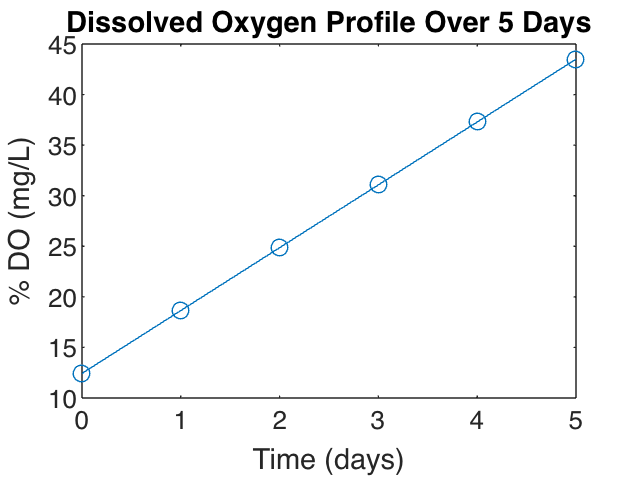

T = [0, 1, 2, 3, 4, 5]; %days
C = 12.43 + (k30*12.43*T); %mg/L

figure
plot(T,C,'o-')
title(["Dissolved Oxygen Profile Over 5 Days"])
ylabel("% DO (mg/L)")
xlabel("Time (days)")

**Discussion:**

- The dissolved oxygen profile shows a linear increase in concentration from a starting value of 12.43 mg/L up to a final value of 43.5 mg/L at $30\degree C$.